# Exercise 1: The Radar Range Equation

This example demonstrates how to use radar system level parameters and the radar range equation to make an estimate of the returned pulse signal to noise ratio (SNR).

## MATLAB Online & Live Scripts

MATLAB Online is a slightly different experience than the typical MATLAB desktop installation.  Many of the tools will be the same, but there may be some differences in visuals and how buttons and options are displayed.

MATLAB Live Scripts are interactive documents that combine MATLAB code with formatted text, equations and images in a single environment called the Live Editor.  In addition, live scripts store and display output alongside the code that creates it.

MATLAB Live Scripts are often divided up into sections, as this one is.  To run one section at a time, use the "Run Section" button in the "Live Editor" panel highlighted below.  The traditional MATLAB "Run" button can be used to run the Live Script in its entirety.  Today, use the "Run Section" button to run one section at a time as subsequent sections are incomplete before you've added your code and running them may result in errors.

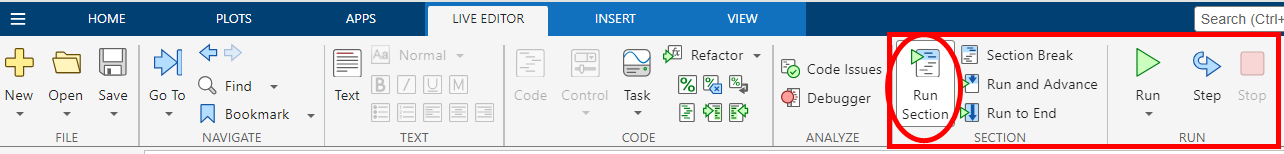

'Tab Completion' is a useful strategy to fill out function name, variable names, and input arguments.

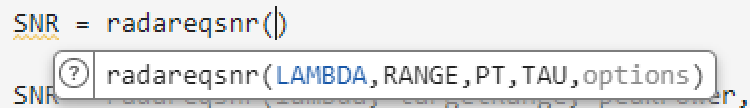

## Find Required SNR for the Desired Probability of Detection and False Alarm

The required signal to noise ratio (SNR) of a received pulse for this system can be determined from the desired probability of detection and probability of false alarm.  The higher the desired probability of detection the higher the SNR needs to be.

requiredSNR = detectability(.9,... % Probability of detection
    1e-6,... % Probability of false alarm
    1); % Number of pulses to integrate

disp(requiredSNR)

## Use Radar Equation to Determine Received SNR


$$SNR = \frac{P_r}{N} = \frac{P_tG^2\lambda^2\sigma}{(4\pi)^3R^4kT_sB_nL}$$


$P_t$ = Peak transmit power in watts

$G_t$ = Transmit/Receive antenna gain

$\lambda$ = Radar wavelength in meters

$\sigma$ = target's nonfluctuating radar cross secion in square meters

L = general loss facto in decibels that accounts for both system and propagation loss

$R_t$ = range from radar to target

$k$ = Boltzmann's constant

$T_s$ = System temperature ($T_s = TF_n$, $T$ = effective noise temperatrue, $F_n$ = Noise Factor)

$B_n$ = bandwidth of the system (equal to the reciprocal of pulse width)

frequency = 6e9; % Hz
lambda = freq2wavelen(frequency); % signal wavelength in meters

range = 40e3; % target range is ~40 kilometers (units are meters)
pt = 1e3; % peak radar power in Watts
tau = 1e-6; % radar pulse width in seconds
rcs = 10; % target radar cross section is ~10 m^2.  This is a name/value pair argument (use RCS=rcs syntax)

ts = 290; % system noise temperature in Kelvin.  This is a name/value pair argument (use Ts=ts syntax)

hpbw = [2; 5]; % [az;el] degrees (clarify single sided vs. double sided)
% For a monostatic radar system, the same hardware is used for transmit and
% receive, so the tx and rx antenna gain will be identical
gain = beamwidth2gain(hpbw, 'CosineRectangular'); % gain in dBi.  This is a name/value pair argument (use Gain=gain syntax)

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radareqsnr' function to calculate the signal to noise
% ratio of the received signal from the target of interest.  Type 'doc
% radareqsnr' into the command line interface for more information.  Supply
% the wavelength, target range, power, pulse width, RCS, system
% temperature and gain as inputs.  Call the output SNR.


%---------------------------------------------------------------------------------------------------

disp(SNR); % dB

## View Returned SNR as a Function of Range

Now calculate the signal to noise ratio as a function of range.  For this system, plot the SNR as a function of range from 20 to 60 km.

ranges = linspace(20e3, 60e3, 100).'; % Ranges from 20 to 40 km in meters

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radareqsnr' function to calculate the signal to noise
% ratio of the received signal from the target of interest.  Type 'doc
% radareqsnr' into the command line interface for more information.  The
% range can be specified as a vector to see the signal to noise ratio as a
% function of range.  Call the output SNR


%---------------------------------------------------------------------------------------------------

plot(ranges * 1e-3, SNR)
yline(requiredSNR, '--r')
title("SNR vs. Range")
ylabel('SNR (dB)')
xlabel('Target Range (km)')
xlim([20, 60])
grid on